# **Practicing Spectral Analysis in 11 questions (Matlab)**

**Prof. Joseph Morlier, ISAE SUPAERO**

How to switch from time domain to frequency domain? are we losing information? is it a global or local transform?

Through 11 questions, this computer lab will allow you, I hope, to understand by practice very complex notions of harmonic analysis.

You will thus have the necessary background to work in the field of Signal processing, vibrations, modal analysis, dynamics of structures etc… 

**Q1:** Define a sinusoid of amplitude 1 for 5 cycles and no phase shift with a sampling period of 0.01s. Display the time signal?


clear all ;close all;
%Q1
dt = .01; 
maxt = 1;
t = 0:dt:(maxt-dt);
nt = length(t);  %length of t

nCycles = 5;
amp = 1; 
phase = 0;
y5 = amp*cos(2*pi*t*nCycles-pi*phase/180); 
figure(1) 
plot(t,y5); xlabel('Time (s)'); set(gca,'XTick',0:.2:maxt); set(gca,'YTick',-1:1); ylabel('Amplitude'); set(gca,'YLim',amp*1.1*[-1,1]);  %'grid' draws dotted lines at the x and y-tick values 
grid

**Q2: **The sinusoid has a frequency of 5Hz (5cycles in 1s). Calculate the spectrum of y5 using 'fft' ?

%Q2
Y5 = fft(y5); 
%Taille de y5 et Y5 ?
whos y5 Y5 

  Name      Size             Bytes  Class     Attributes

  Y5        1x100             1600  double    complex   
  y5        1x100              800  double              



%Classe de Y ?
Y5(1:10)'

ans =    0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  50.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i


**Q3:** Now add to the graph a new sinusoid of amplitude 2 and phase shift 30°. Visualize 7 cycles ?

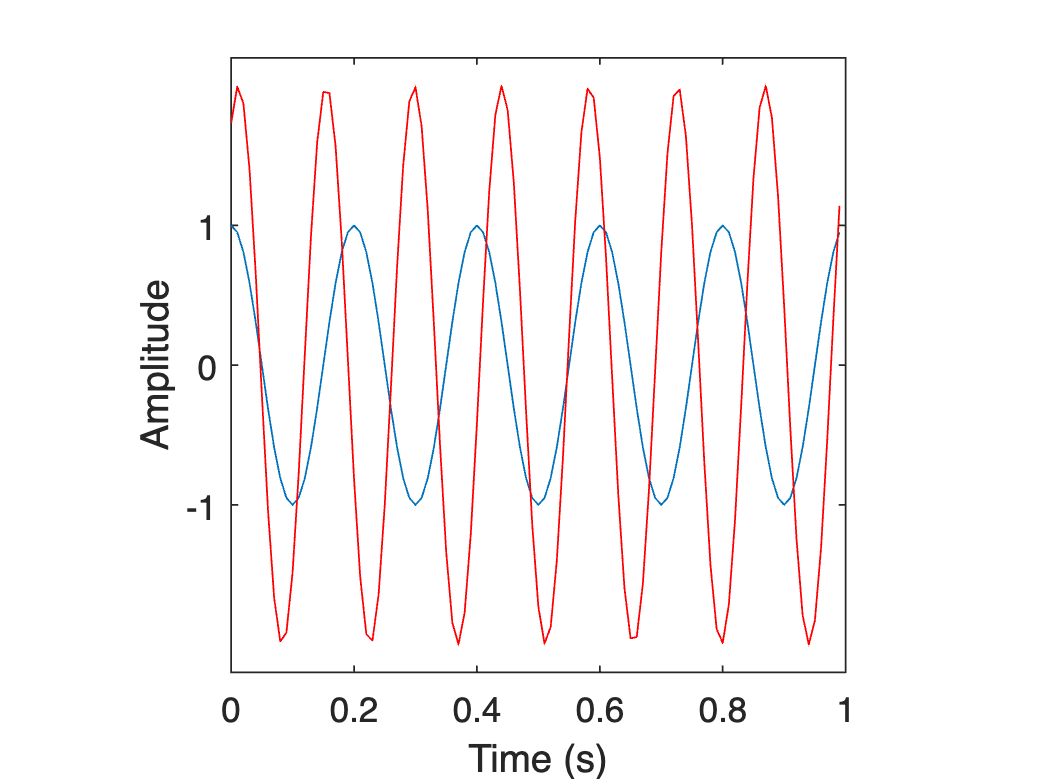

%Q3
nCycles = 7; 
amp = 2;  %around 1.15 
phase = 30;  %degrees  
y7 = amp*cos(2*pi*t*nCycles-pi*phase/180); 
figure(1)
hold on
plot(t,y7,'r-'); xlabel('Time (s)'); 
set(gca,'XTick',0:.2:maxt); 
set(gca,'YTick',-1:1); 
ylabel('Amplitude'); 
set(gca,'YLim',amp*1.1*[-1,1]);
axis square 
grid off  

Y7 = fft(y7);

**Q4: **Compare the phase of Y5 and Y7. Visualize the graph real part vs imaginary part (cycle) ?

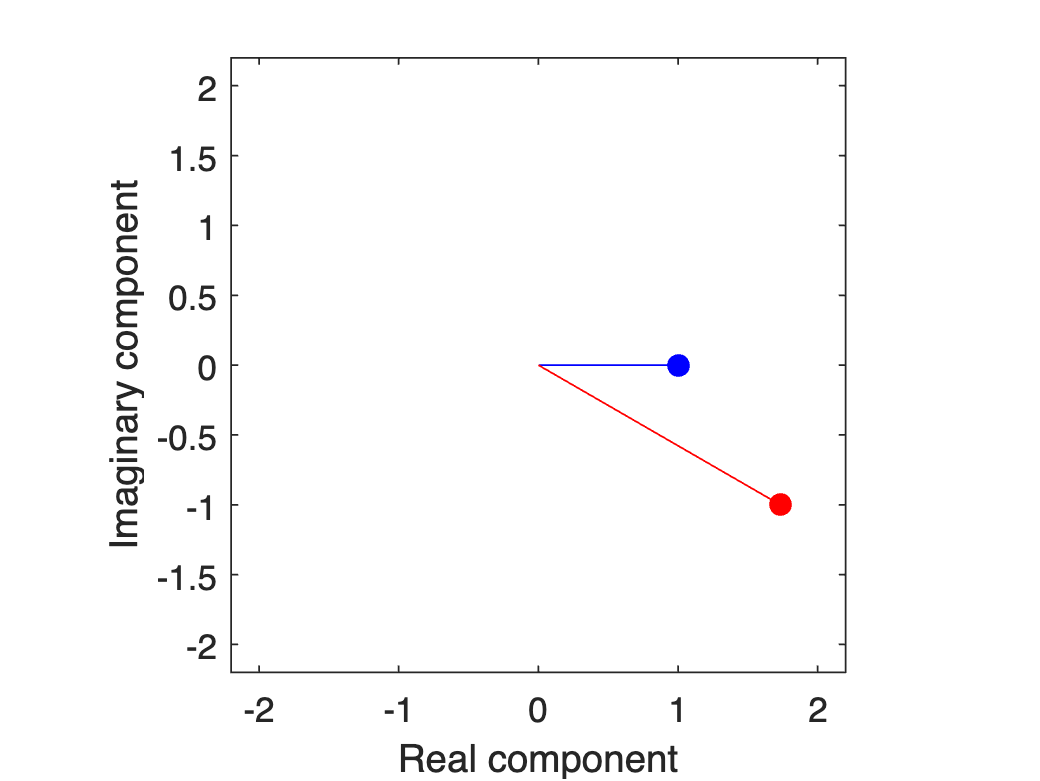

%Q4
figure
plot([0,2*Y5(6)/nt],'b-'); hold on
h5=plot(2*Y5(6)/nt,'bo','MarkerFaceColor','b');
axis equal  
xlabel('Real component')
ylabel('Imaginary component');
hold on
plot([0,2*Y7(8)/nt],'r-');
h7= plot(2*Y7(8)/nt,'ro','MarkerFaceColor','r');
set(gca,'XLim',1.1*amp*[-1,1]); 
set(gca,'YLim',1.1*amp*[-1,1]);



amp5 = 2*abs(Y5(6))/nt; 
phase5 = -180*angle(Y5(6))/pi;
amp7 = 2*abs(Y7(8))/nt; 
phase7 = -180*angle(Y7(8))/pi;

**Q5:** We generate a more complicated sinusoid. Display the time signal ?

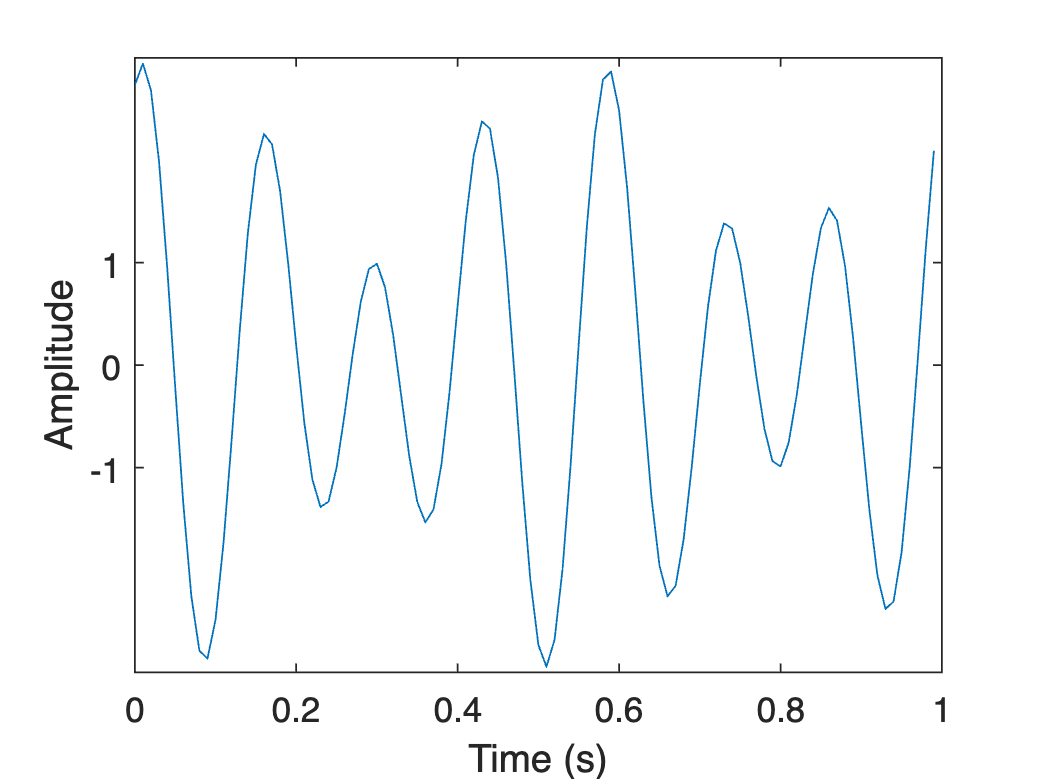

%Q5
y57 = y5+y7;  
figure 
plot(t,y57); xlabel('Time (s)');
set(gca,'XTick',0:.2:2); 
set(gca,'YTick',-1:1); ylabel('Amplitude');

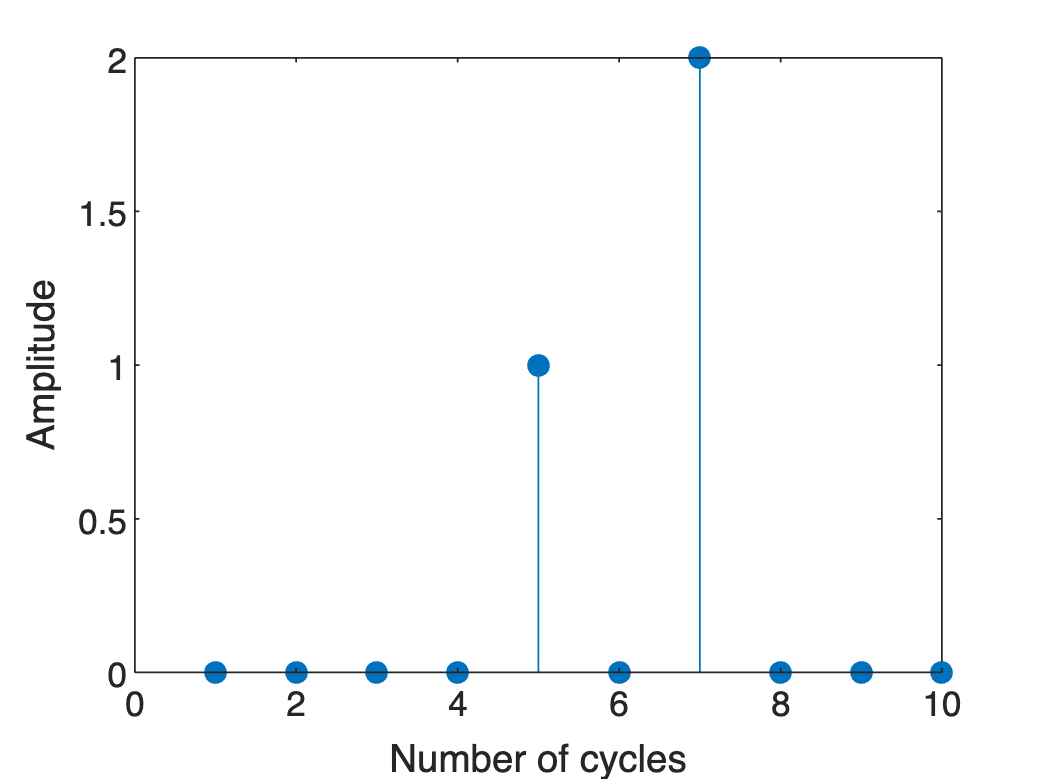



%Tracer son spectre en utilisant ?fft?

Y57 = fft(y57);  
% We'll plot the amplitudes of the first 10 sinusoids as a 'stem' plot 
id = 2:11;  %sinusoids of periods 1 through 10  
figure
stem(2*abs(Y57(id))/nt,'fill')  
xlabel('Number of cycles') 
ylabel('Amplitude');

**Q6:** What is “Full” spectrum ?

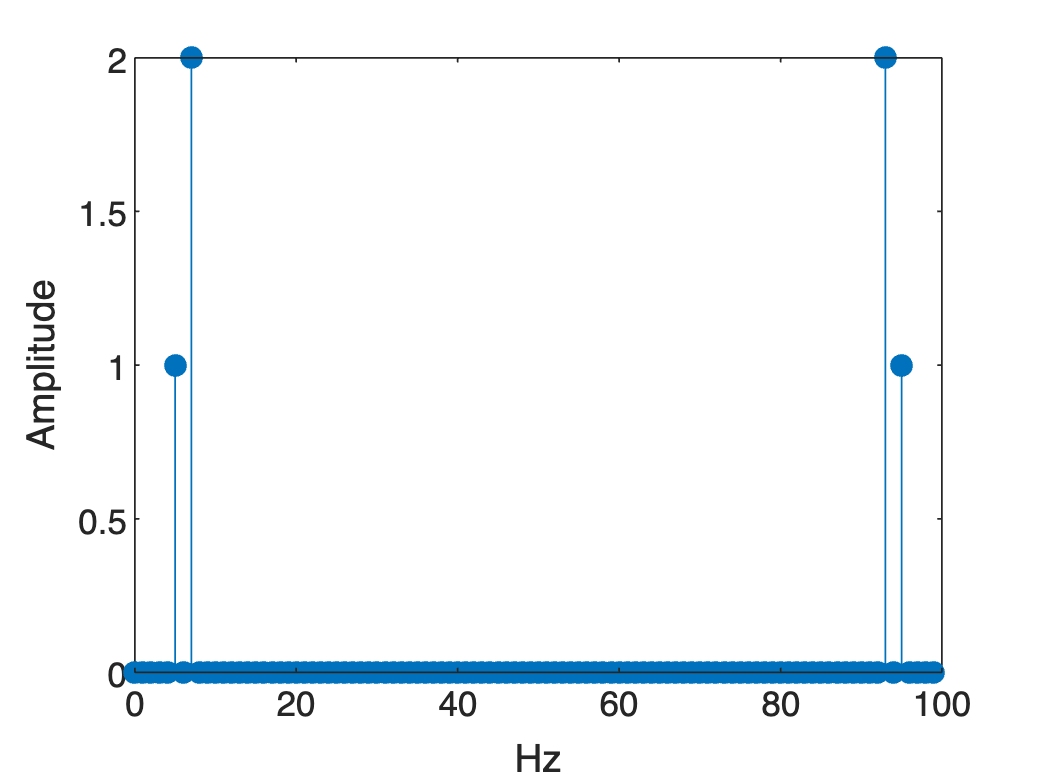

%Q6
Fs=1/dt;
F=(0:nt-1)*Fs/nt;
figure
stem(F,2*abs(Y57)/nt,'fill') 
xlabel('Hz');
ylabel('Amplitude');

**Q7:** Examples of interesting spectra for time-frequency equivalence  ?

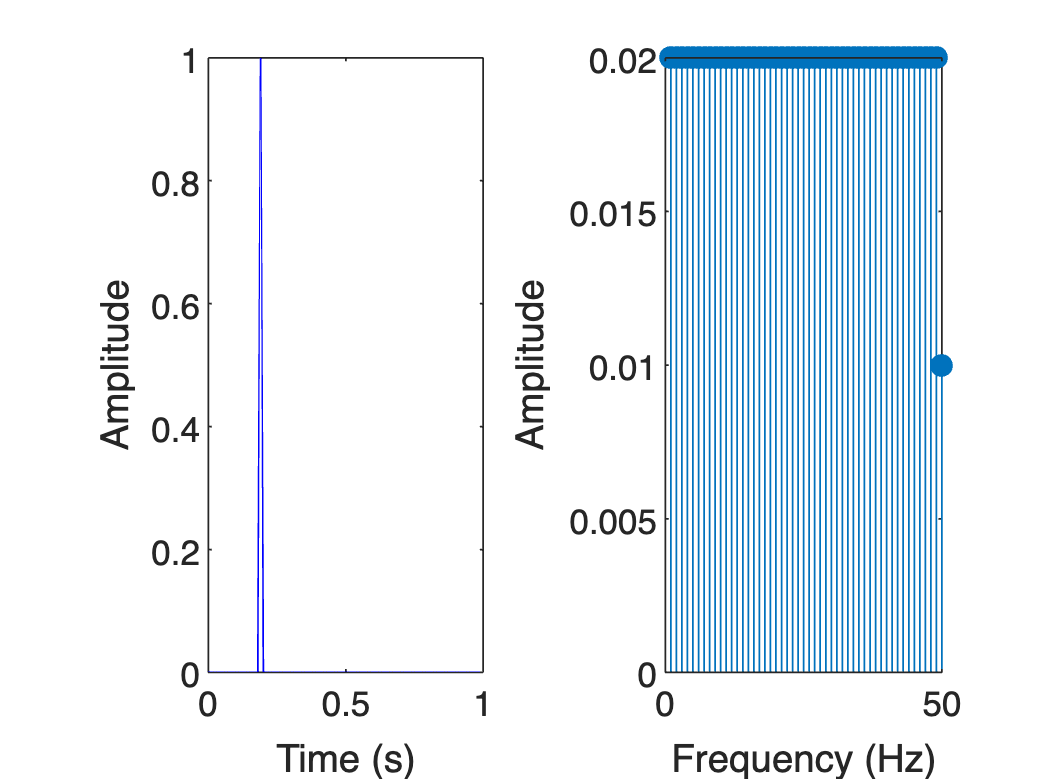

%Q7
figure;
y = zeros(size(t)); y(20) = 1;  plotFFT(t,y);

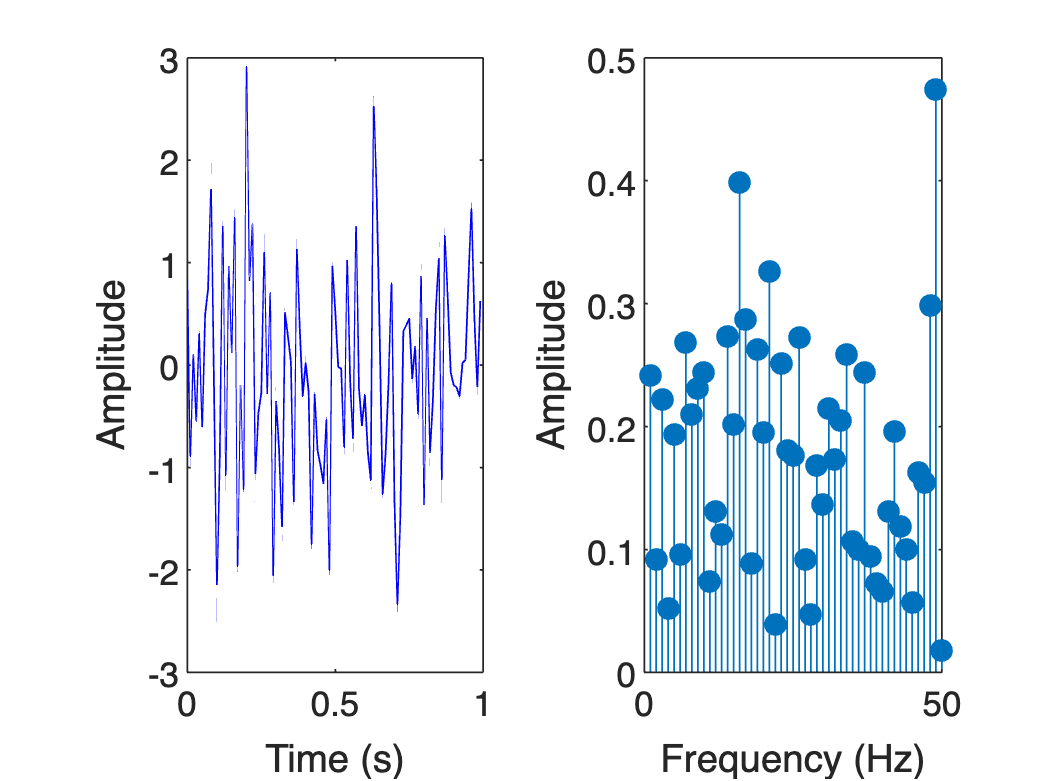

figure;
y = randn(size(t)); plotFFT(t,y);

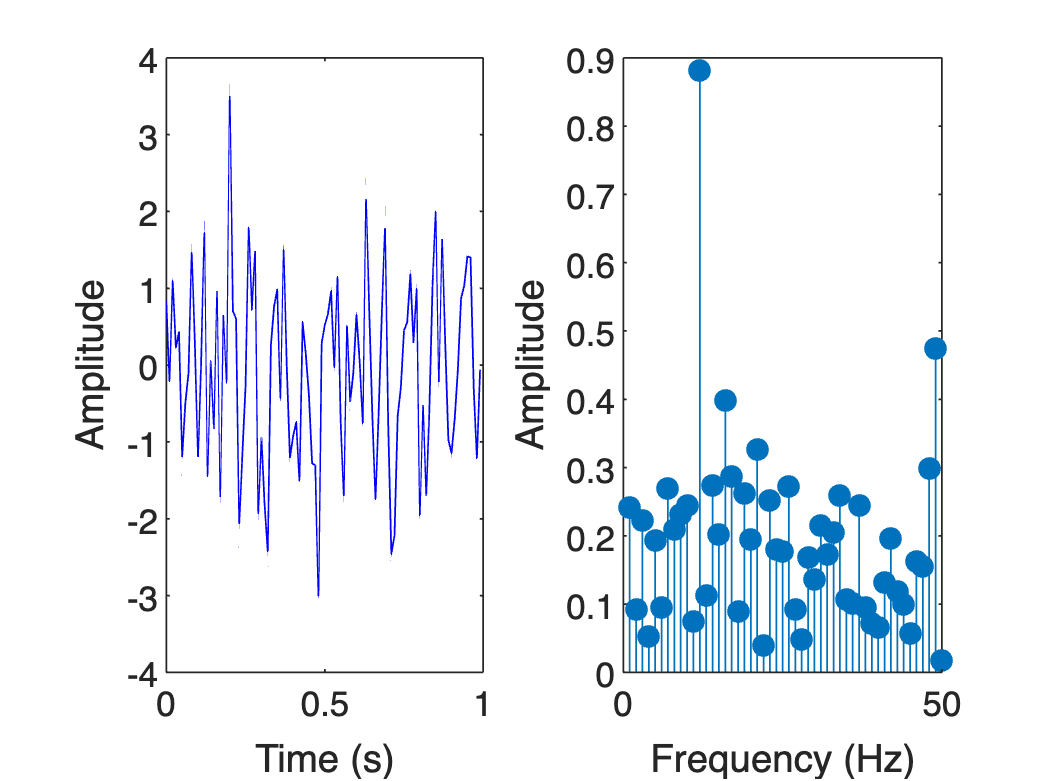

figure;
nCycles = 12; y = y+sin(2*pi*nCycles*t); plotFFT(t,y);

**Q8:** A bit of vibration ;) Visualize the ‘handel’ signal ?

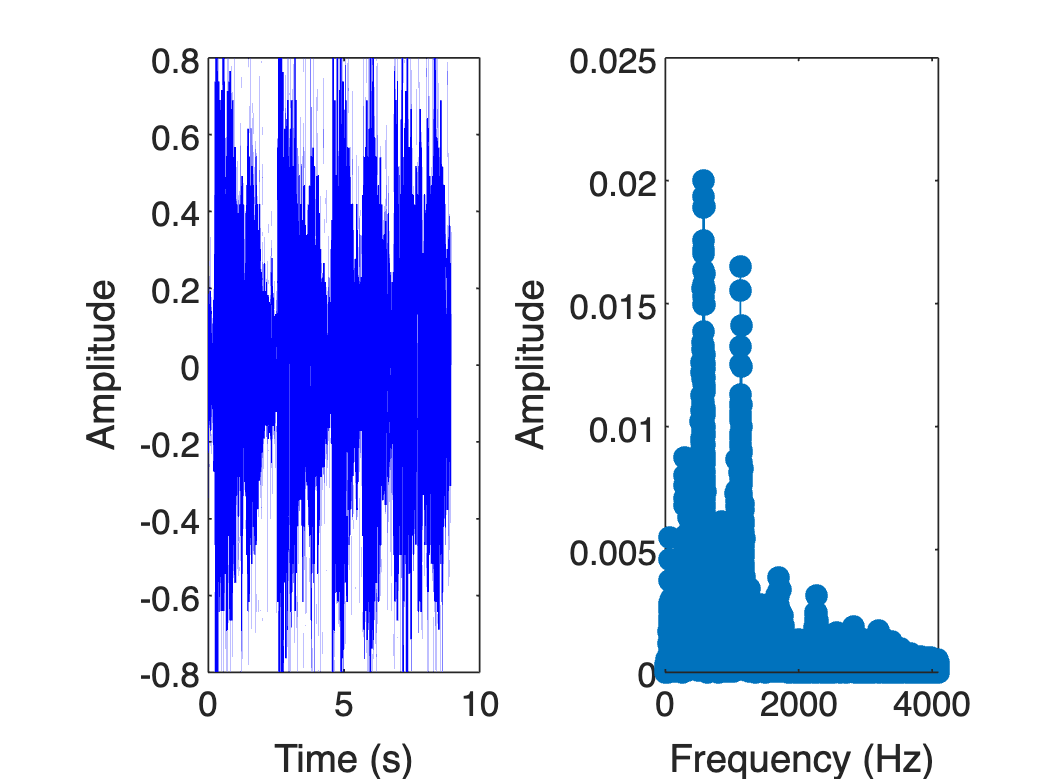

%Q8
load handel 
%The file contains two variables, the time-course of the sound, y and the sampling rate, Fs (in Hz). We can create our own time vector from this information:
maxt = length(y)/Fs;
t = linspace(0,maxt,length(y));  
% Here's a plot of the time-course of the sound hander
% 
% figure
% plot(t,y);
% xlabel('Time (sec)');

%L??couter maintenant?en appuyant sur une touche
%pause;
%ylim = get(gca,'YLim');
%timeH = plot([0,0],ylim','r-','LineWidth',2);  
sound(y,Fs);  tic 
% while toc<maxt     
% set(timeH,'XData',toc*[1,1])     
% drawnow 
% end  
% delete(timeH);

%Visualier le spectre (amplitude) et le signal temporel
figure;
plotFFT(t,y);

**Q9:** Now we zoom, listen and watch the spectrum

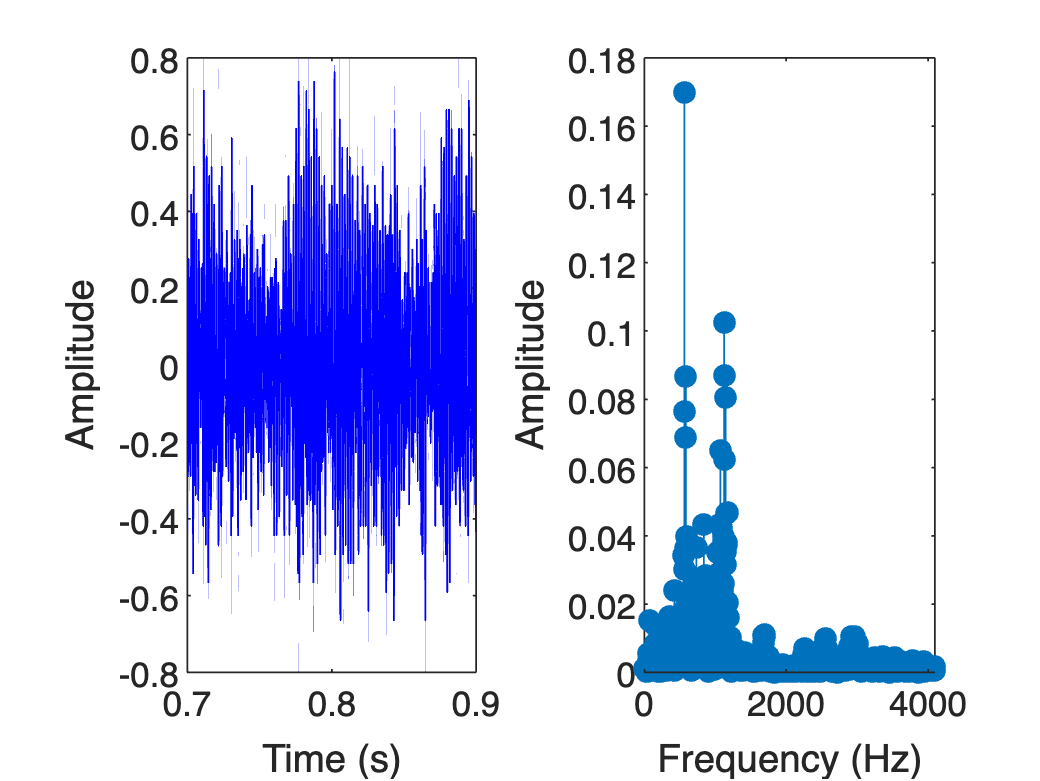

%Q9
tLo = .7; tHi = .9;  
y1 = y(t>tLo & t<tHi); 
maxt = length(y1)/Fs; 
t1 = t(t>tLo & t<tHi);  %linspace(0,maxt,length(y1));
figure;
%sound(y1,Fs);
plotFFT(t1,y1) ;

**Q10:** Now display the evolution of the spectrum over time

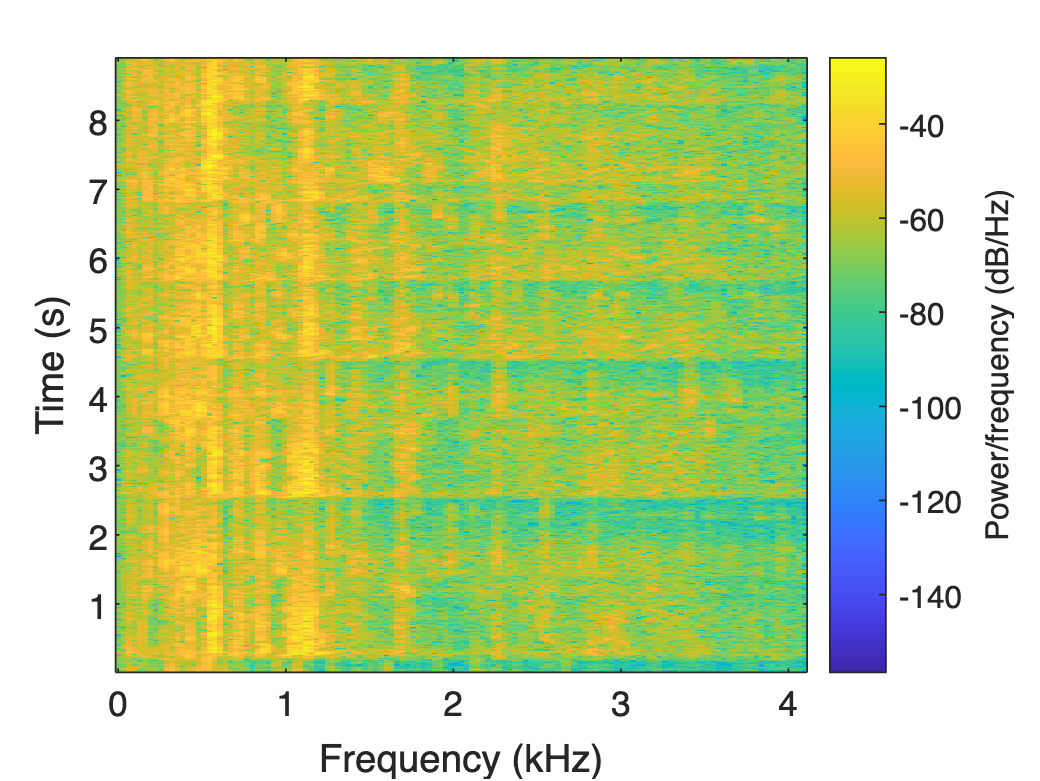

%Q10
figure
spectrogram(y,256,120,256,Fs); % Display the spectrogram

**Q11:** How to estimate a transfer function (FRF?) from a measured displacement ys and a measured force u over time? 

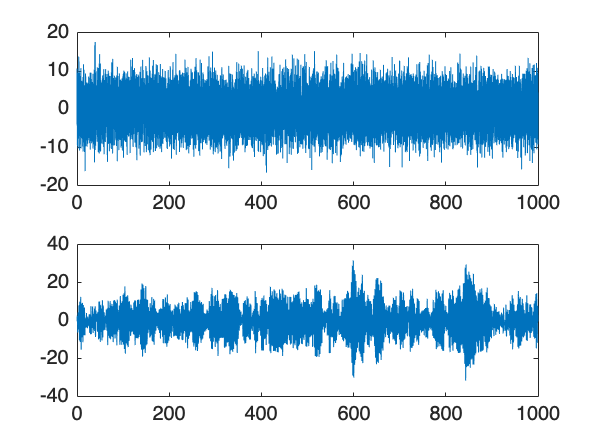

%Q11
Ts=0.05;
Fs=1/Ts;
load data;
u=data(:,1);
ys=data(:,2);
t=0:Ts:(length(u)-1)*Ts;
figure; subplot(211);plot(t,u);subplot(212);plot(t,ys);

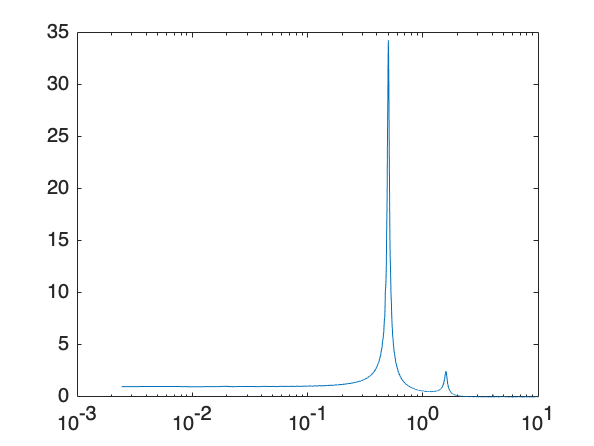

[txy,f]=tfestimate(u,ys,[],[],[],Fs);
figure
semilogx(f,(abs(txy)))